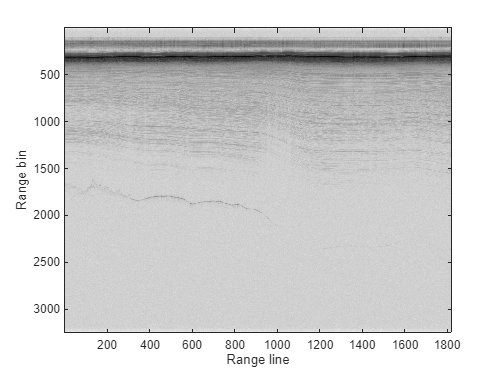

addpath C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_standard\20240105_02\
addpath C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_layer\20240105_02\

load Data_img_01_20240105_02_005.mat
load Data_20240105_02_005.mat

close all
echo = load('Data_img_01_20240105_02_005.mat','Data','Time','GPS_time');
h_fig = figure;
h_axes = axes;
imagesc(lp(echo.Data),'parent',h_axes);
colormap(h_axes,1-gray(256));
xlabel('Range line','parent',h_axes);
ylabel('Range bin','parent',h_axes);

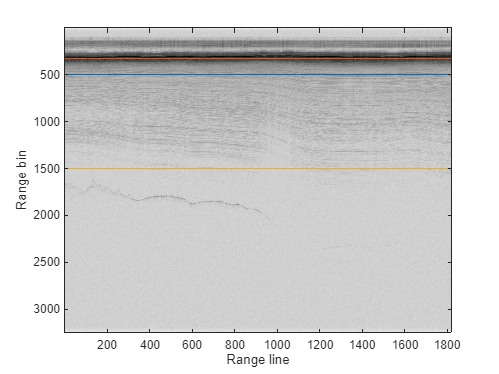

% can I take a column out of Data and use the value to mark an "intensity"
% in reflection, therefore an "intensity" or power?

imagesc(lp(echo.Data),'parent',h_axes);
colormap(h_axes,1-gray(256));
xlabel('Range line','parent',h_axes);
ylabel('Range bin','parent',h_axes);
hold on
x = linspace(0, size(Data, 1), size(Data, 1));
y1 = linspace(500, 500, size(Data, 1));
y2 = linspace(324, 324, size(Data, 1));
y3 = linspace(1500, 1500, size(Data, 1));
plot(x, y1)
plot(x, y2)
plot(x, y3)

hold off

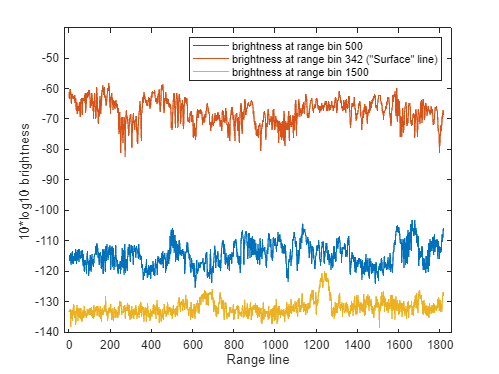


% layer = interp1(gps_time, twtt(2,:), GPS_time);
% still not sure what this does tbh :(

brightness = Data(500, :);
plot(10*log10(brightness))
hold on
d = linspace(324, 324, size(Data, 1));
brightness2 = Data(324, :);
plot(10*log10(brightness2))
f = linspace(1500, 1500, size(Data, 1));
brightness3 = Data(1500, :);
plot(10*log10(brightness3))
legend('brightness at range bin 500', 'brightness at range bin 342 ("Surface" line)', 'brightness at range bin 1500')
xlim([-20 1856]);
ylim([-140.1 -40.1]);
xlabel('Range line');
ylabel('10*log10 brightness ');

hold off